# Actividad 6: Modelado de Energía Cinética

Ana Itzel Hernández Garía A01737526

**Obtener **el modelo de la energía cinética total para cada una de las siguientes configuraciones de robots manipuladores

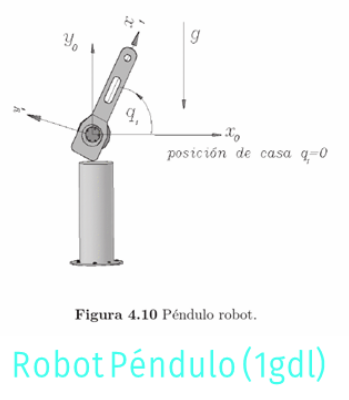

## Péndulo

Limpieza de pantalla

clear all
close all
clc

Declaración de variables simbólicas

syms th1(t)  t  %Angulos de cada articulación
syms m1 Ixx1 Iyy1 Izz1  %Masas y matrices de Inercia
syms l1 lc1   %l=longitud de eslabones y lc=distancia al centro de masa de cada eslabón
syms pi g a cero 

Vector de coordenadas articulares

Q= [th1];

Vector de velocidades articulares

Qp= diff(Q, t);

Creamos el vector de aceleraciones articulares

Qpp= diff(Qp, t);

Configuración del robot (0 para junta rotacional, 1 para junta prismática)

RP=[0];

Número de grado de libertad del robot

GDL= size(RP,2);
GDL_str= num2str(GDL);

### Articulación 1

Posición de la articulación 1 respecto a 0

P(:,:,1)= [l1*cos(th1); l1*sin(th1);0];

Matriz de rotación de la junta 1 respecto a 0

R(:,:,1)= [cos(th1) -sin(th1)  0;
           sin(th1)  cos(th1)  0;
           0         0         1];

Vector de ceros

Vector_Zeros= zeros(1, 3);

### Matrices

Inicializamos las matrices de transformación Homogénea locales

A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

Inicializamos las matrices de transformación Homogénea globales

T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

Inicializamos las posiciones vistas desde el marco de referencia inercial

PO(:,:,GDL)= P(:,:,GDL); 

Inicializamos las matrices de rotación vistas desde el marco de referencia inercial

RO(:,:,GDL)= R(:,:,GDL); 


for i = 1:GDL
    i_str= num2str(i);
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    T(:,:,i)= simplify(T(:,:,i));

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);

end

#### Calculamos el jacobiano y angular lineal de forma analítica

Inicializamos jacobianos analíticos 

Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
    elseif RP(k)==1 
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

#### SubMatrices de Jacobianos

Jacobiano lineal obtenido de forma analítica

Jv_a= simplify (Jv_a);

Jacobiano ángular obtenido de forma analítica

Jw_a= simplify (Jw_a);

Matriz de Jacobiano Completa

Jac= [Jv_a;
      Jw_a];
Jacobiano= simplify(Jac)

$$Jacobiano = \left(\begin{array}{c} -l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ 0\\ 0\\ 0\\ 1 \end{array}\right)$$

#### Vectores de Velocidades Lineales y Angulares

Velocidad lineal

disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 3'); V=simplify (Jv_a*Qp)

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 3


$$V(t) = \left(\begin{array}{c} -l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)\\ l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)\\ 0 \end{array}\right)$$

Velocidad angular

disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 3'); W=simplify (Jw_a*Qp)

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 3


$$W(t) = \left(\begin{array}{c} 0\\ 0\\ \frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right) \end{array}\right)$$

### Energía Cinética

Distancia del origen del eslabón a su centro de masa

#### Vectores de posición respecto al centro de masa

P01=subs(P(:,:,1)/2, l1, lc1) %La función subs sustituye l1 por lc1 en 

$$P01 = \left(\begin{array}{c} \frac{{\mathrm{lc}}_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)}{2}\\ \frac{{\mathrm{lc}}_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)}{2}\\ 0 \end{array}\right)$$

                              %la expresión P(:,:,1)/2

#### Matrices de inercia para cada eslabón

Eslabón 1

I1=[Ixx1 0 0; 
    0 Iyy1 0; 
    0 0 Izz1];

#### **Función de energía cinética**

Extraemos las velocidades lineales del efector final en cada eje

V=V(t); 
Vx= V(1,1);
Vy= V(2,1);
Vz= V(3,1);

Extraemos las velocidades angular del efector final en cada ángulo de Euler

W=W(t);
W_pitch= W(1,1);
W_roll= W(2,1);
W_yaw= W(3,1);

### Energía cinética para cada uno de los eslabones

#### Eslabón 1

V1_Total= V+cross(W,P01); %Se suma la velocidad lineal producida por la
                          % velocidad angular producida en el punto P01             
K1= (1/2*m1*(V1_Total))'*(V1_Total) + (1/2*W)'*(I1*W);
disp('Energía Cinética en el Eslabón 1');

Energía Cinética en el Eslabón 1


K1= simplify (K1);K1

$$K1 = \frac{{\mathrm{Izz}}_{1}\,{\left|\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)\right|}^{2}}{2}+\frac{{\left|\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)\right|}^{2}\,\cos\left(\bar{{\mathrm{th}}_{1}\left(t\right)}-{\mathrm{th}}_{1}\left(t\right)\right)\,\bar{m_{1}}\,\left(2\,{\mathrm{lc}}_{1}\,{\left|l_{1}\right|}^{2}+l_{1}\,{\left|{\mathrm{lc}}_{1}\right|}^{2}\right)\,\left(2\,l_{1}+{\mathrm{lc}}_{1}\right)}{8\,l_{1}\,{\mathrm{lc}}_{1}}$$


K_Total= simplify (K1)

$$K\_Total = \frac{{\mathrm{Izz}}_{1}\,{\left|\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)\right|}^{2}}{2}+\frac{{\left|\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)\right|}^{2}\,\cos\left(\bar{{\mathrm{th}}_{1}\left(t\right)}-{\mathrm{th}}_{1}\left(t\right)\right)\,\bar{m_{1}}\,\left(2\,{\mathrm{lc}}_{1}\,{\left|l_{1}\right|}^{2}+l_{1}\,{\left|{\mathrm{lc}}_{1}\right|}^{2}\right)\,\left(2\,l_{1}+{\mathrm{lc}}_{1}\right)}{8\,l_{1}\,{\mathrm{lc}}_{1}}$$

### Energía potencial

Obtenemos las alturas respecto a la gravedad

h1= P01(2); %Tomo la altura paralela al eje y

Energía potencial de cada eslabón

U_Total=m1*g*h1

$$U\_Total = \frac{g\,{\mathrm{lc}}_{1}\,m_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)}{2}$$

Obtenemos el Lagrangiano

Lagrangiano= simplify (K_Total-U_Total);

Modelo de Energía

H= simplify (K_Total+U_Total)

$$H = \frac{{\mathrm{Izz}}_{1}\,{\left|\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)\right|}^{2}}{2}+\frac{g\,{\mathrm{lc}}_{1}\,m_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)}{2}+\frac{{\left|\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)\right|}^{2}\,\cos\left(\bar{{\mathrm{th}}_{1}\left(t\right)}-{\mathrm{th}}_{1}\left(t\right)\right)\,\bar{m_{1}}\,\left(2\,{\mathrm{lc}}_{1}\,{\left|l_{1}\right|}^{2}+l_{1}\,{\left|{\mathrm{lc}}_{1}\right|}^{2}\right)\,\left(2\,l_{1}+{\mathrm{lc}}_{1}\right)}{8\,l_{1}\,{\mathrm{lc}}_{1}}$$